Prepare for simulated VAR(3) data generation.

rng(1); % for reproducibility

L=3; % VAR model order
P=2; % number of pairs that we will ask GCA to compute
K=3; % number of latent sources
D=4; % number of sensors
N=5000; % number of time points
sigma_inn=1; % standard deviation of innovation process
sigma_sensor=0.01; % standard deviation of sensor noise

Generate the VAR(3) model matrix according to Stokes & Purdon (<-- huge fans of Granger). In this system, s1 --> s2 and s2 --> s3. 

% parameters of the VAR system matrix
r1=0.9; theta1=40/120*2*pi;
r2=0.7; theta2=10/120*2*pi;
r3=0.8; theta3=50/120*2*pi;

% create the VAR system matrix here
B(:,:,1)=[2*r1*cos(theta1) 0 0; -0.356 2*r2*cos(theta2) 0; 0 -0.3098 2*r3*cos(theta3) ]; % lag 1
B(:,:,2)=[-r1.^2 0 0; 0.7136 -r2.^2 0; 0 0.5 -r3.^2];  % lag 2
B(:,:,3)=[0 0 0; -0.356 0 0; 0 -0.3098 0];  % lag 3

B

B = B(:,:,1) =

   -0.9000         0         0
   -0.3560    1.2124         0
         0   -0.3098   -1.3856


B(:,:,2) =

   -0.8100         0         0
    0.7136   -0.4900         0
         0    0.5000   -0.6400


B(:,:,3) =

         0         0         0
   -0.3560         0         0
         0   -0.3098         0


% Note that s1 --> s2, s2 --> s3

Generate the VAR proceess of the *latent* sources. Note that these are not the observations. 

S(:,1:L)=randn(K,L);
for n=L+1:N
    for p=1:L
        S(:,n)=B(:,:,p)*S(:,n-p);
    end
    S(:,n)=S(:,n)+sigma_inn*randn(K,1); 
end

Plot the latent sources.

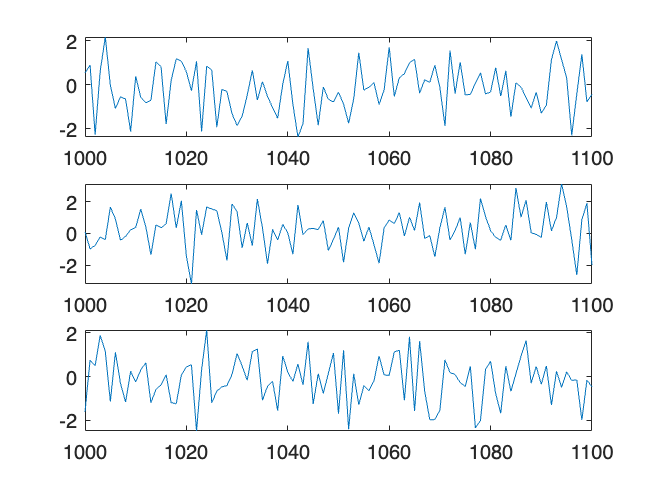

samples_to_show=1000:1100;
figure;
for i=1:K
    subplot(K,1,i)
    plot(samples_to_show, S(i,samples_to_show))
end

Generate the observed data.

A=rand(D,K); % the mixing matrix ~ U(0,1)

% simulate projections to array and add noise
X=A*S + sigma_sensor*randn(D,N);

Plot the observed data.

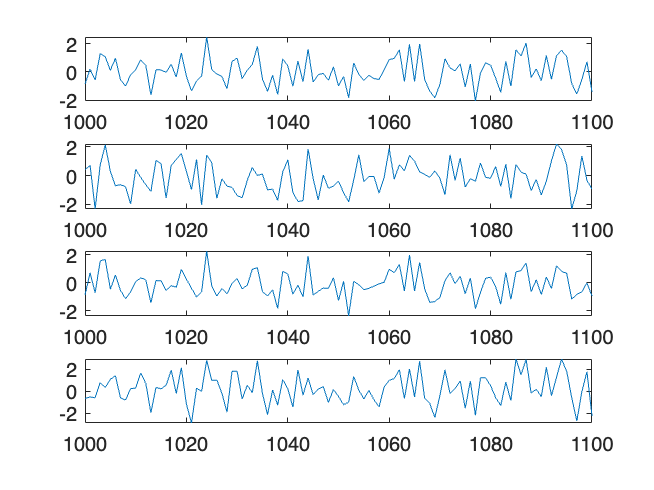

figure;
for i=1:D
    subplot(D,1,i)
    plot(samples_to_show, X(i,samples_to_show))
end

Center the observed data.

X = bsxfun(@minus, X, mean(X,2));

Transpose the data as GCA expects time in row dimension, channel in column dimension.

X = X.';
size(X)

ans =         5000           4


Run GCA.

max_iterations=50; % max number of iterations in search
reg_parameter=inf; % no regularization
[What,Vhat,gcs,gcaStats] = runGcaTrAlt(X,L,P,max_iterations,reg_parameter);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

Apply the GCA filters to the data.

X = X.'; % back to (channel, time)
Y = What.'*X;
Z = Vhat.'*X;

Compare the recovered sources. We expect that: y1 ~ s1, y2  ~ s2, z1 ~ s2, z2 ~ s3. 

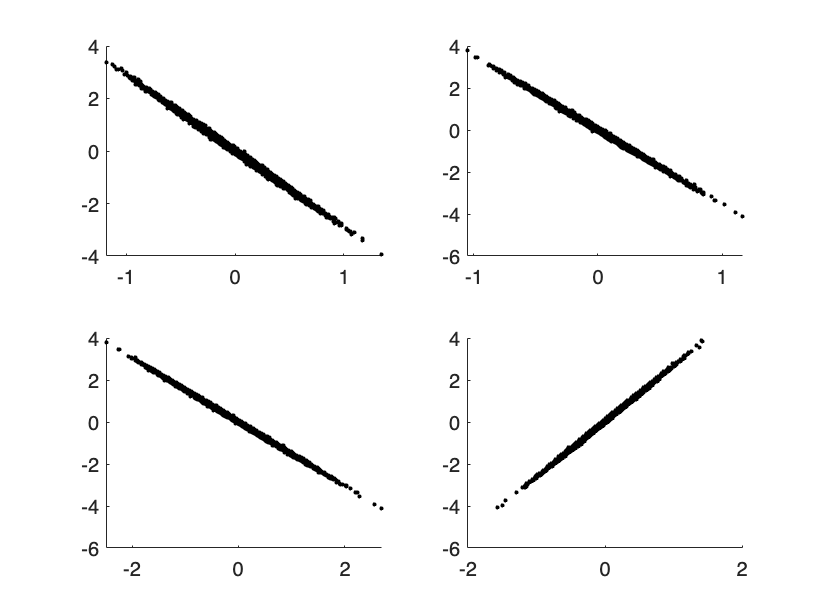

figure;
subplot(221)
scatter(Y(1,:),S(1,:),'k.')
subplot(222)
scatter(Y(2,:),S(2,:),'k.')
subplot(223)
scatter(Z(1,:),S(2,:),'k.')
subplot(224)
scatter(Z(2,:),S(3,:),'k.')

Note that GCA is unable to recover the amplitude or sign of the latent sources, so some scatter plots will show up as inverse correlation. Note also that on some machines (random number seeds), the pairs may flip. 

Finally, compare the time series of latent and recovered sources. 

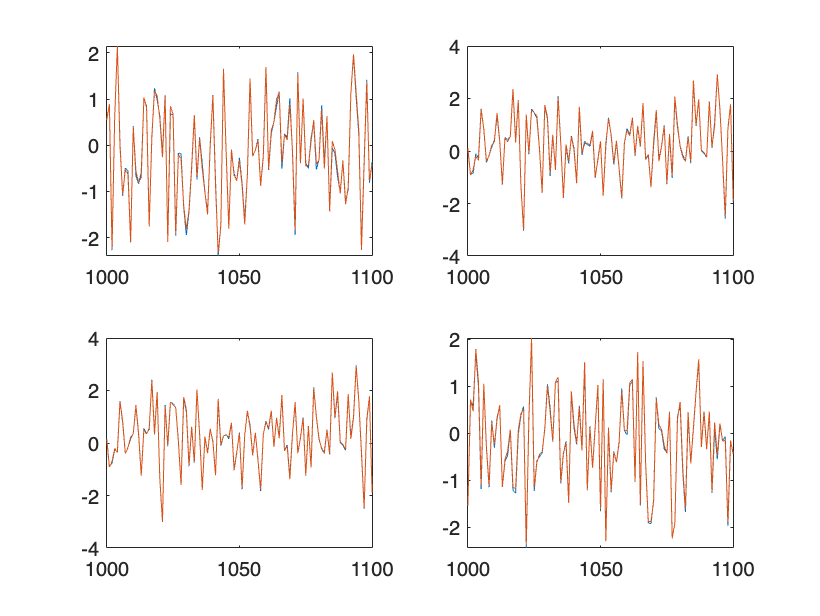

% standardize to unit norm to facilitate comparison
Yn = bsxfun(@rdivide,Y,std(Y,[],2));
Zn = bsxfun(@rdivide,Z,std(Z,[],2));
Sn = bsxfun(@rdivide,S,std(S,[],2));

% from the scatter plots, we know that y1, y2, and z1 are inverted
% so we flip their sign

figure;
% s1 versus y1
subplot(221)
plot(samples_to_show,-Yn(1,samples_to_show), ...
    samples_to_show, Sn(1,samples_to_show))

% s2 versus y2
subplot(222)
plot(samples_to_show,-Yn(2,samples_to_show), ...
    samples_to_show, Sn(2,samples_to_show))

% s2 versus z1
subplot(223)
plot(samples_to_show,-Zn(1,samples_to_show), ...
    samples_to_show, Sn(2,samples_to_show))

% s3 versus z2
subplot(224)
plot(samples_to_show,Zn(2,samples_to_show), ...
    samples_to_show, Sn(3,samples_to_show))